clc, clear, close all, format short
syms s t
Y = (1262646+288162*s)/106301/(s*s+8*s+25)

$$Y = \frac{\frac{288162\,s}{106301}+\frac{1262646}{106301}}{s^{2}+8\,s+25}$$

y = ilaplace(Y)

$$y = \frac{288162\,{\mathrm{e}}^{-4\,t}\,\left(\cos\left(3\,t\right)+\frac{291\,\sin\left(3\,t\right)}{2287}\right)}{106301}$$

format rat
288162*291/2287/106301

ans =      724/2099  



s = tf('s');
T = 2700*7*(s+25)/(s+1)/(s+45)/(s+60)/(s*s+8*s+25)

T =
 
                     18900 s + 472500
  ------------------------------------------------------
  s^5 + 114 s^4 + 3678 s^3 + 27790 s^2 + 91725 s + 67500
 
연속시간 전달 함수입니다.



pole(T)

ans =      -60        +    0i      
     -45        +    0i      
      -4        +    3i      
      -4        -    3i      
      -1        +    0i      


zero(T)

ans =      -25       


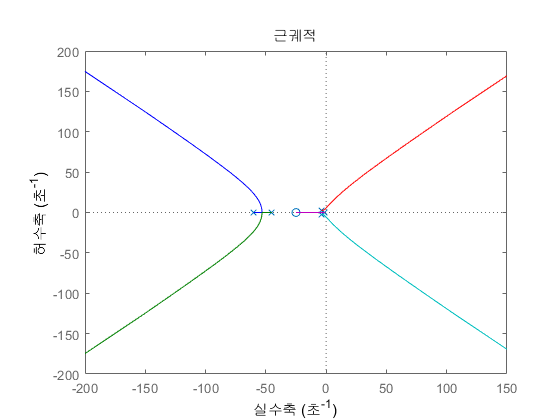

rlocus(T)

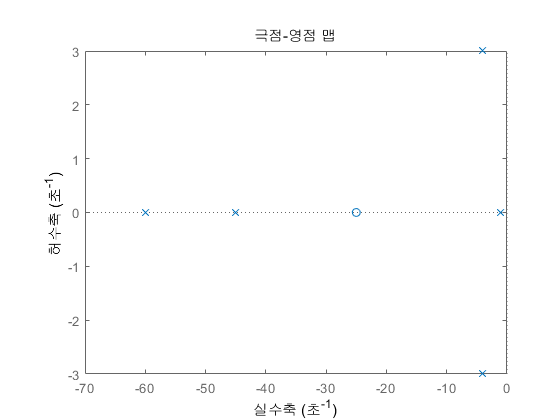

pzmap(T)

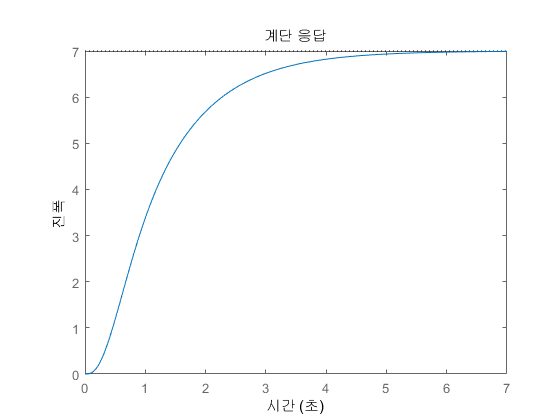

step(T)

stepinfo(T)

ans = 다음 필드를 포함한 struct :
        RiseTime: 2125/947
    SettlingTime: 2217/523
     SettlingMin: 4198/665
     SettlingMax: 3545/507
       Overshoot: 0
      Undershoot: 0
            Peak: 3545/507
        PeakTime: 2042/287


clear, syms s
ilaplace(1/s/s)

$$ans = t$$